md = loadmodel('/Users/rishi/Desktop/ISSM/examples/Pig/Models/Stange_Inverted.mat');

## Read the Paolo netcdf data

paolo ='/Users/rishi/Desktop/ISSM/examples/Data/Paolo_Ice_thickness_1996_2017.nc';

% read the parameters from the paolo datasets
x = double(ncread(paolo,'x')); 
y = double(ncread(paolo,'y'));
bmb = ncread(paolo,'melt'); % basal mass balance
smb = ncread(paolo,'smb'); % surface mass balance

% mean of the mass balance from Paolo
smb_mean   = ncread(paolo,'smb_mean')'; % mean surface mass balance
bmb_mean = double(ncread(paolo,'melt_mean')); % mean basal melt rate

% transpose the basal mass balance and surface mass balance matrices
bmb = permute(bmb, [2 1 3]);
smb = permute(smb, [2 1 3]);

% flip the y and the data matrices to read in ISSM
y = flipud(y);
bmb = flip(bmb, 1);
smb = flip(smb, 1);

% convert the data into a yearly data for the convenience
smb_yearly = squeeze(mean(reshape(smb,length(x),length(y),4,104/4),3));
bmb_yearly = squeeze(mean(reshape(bmb,length(x),length(y),4,104/4),3));

% read the time parameters
TIME = ncread(paolo,'time');
converted_time = datetime(1950, 1, 1) + days(TIME); % Convert to datetime
YEARS = unique(year(converted_time));

##  Allocate basal melt and surface mass balance forcing array 

md.basalforcings.floatingice_melting_rate = zeros(md.mesh.numberofvertices + 1, numel(YEARS));
md.basalforcings.floatingice_melting_rate(end, :) = YEARS;

md.smb.mass_balance = zeros(md.mesh.numberofvertices + 1, numel(YEARS));
md.smb.mass_balance(end, :) = YEARS;

% Loop over time steps
for i = 1:numel(YEARS)
    % bmb forcing
    md.basalforcings.floatingice_melting_rate (1:end-1, i) = ...
        InterpFromGridToMesh(x, y, bmb_yearly(:,:,i), md.mesh.x, md.mesh.y, 0);
    % smb forcing
    md.smb.mass_balance (1:end-1, i) = ...
        InterpFromGridToMesh(x, y, smb_yearly(:,:,i), md.mesh.x, md.mesh.y, 0);
end

% set the grounded ice melting rate
md.basalforcings.groundedice_melting_rate = zeros(md.mesh.numberofvertices,1);

% change the nan values to zero for the sake of model run
md.basalforcings.floatingice_melting_rate (isnan(md.basalforcings.floatingice_melting_rate)) = 0;
md.smb.mass_balance (isnan(md.smb.mass_balance)) = 0;

## check whether the surface mass baalance is properly implemented

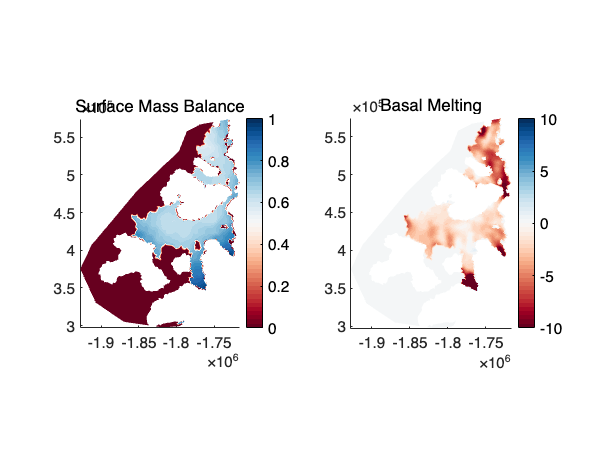

plotmodel(md,'data',md.smb.mass_balance(1:end-1, 2),'title','Surface Mass Balance','caxis#1',([0 1]),...
    'data',md.basalforcings.floatingice_melting_rate(1:end-1, 2),'title','Basal Melting','caxis#2',([-10 10]))

colormap(brewermap(50,'RdBu'))

## Set Up The Transient run for the simulation of 20 years

%Indicate the components of transient to activate
md.transient.ismasstransport = 1;
md.transient.isstressbalance = 1;
md.transient.isgroundingline = 1;
md.transient.ismovingfront = 0;
md.transient.isthermal = 0;

%Specify time steps and length of simulation (years)
md.timestepping.start_time = 0;
md.timestepping.time_step = 0.1;
md.timestepping.final_time = 20;

%Disable inverse method
md.inversion.iscontrol = 0;

%Initialize fields for transient and add boundary conditions
md.initialization.vx = md.results.StressbalanceSolution.Vx;
md.initialization.vy = md.results.StressbalanceSolution.Vy;
md.initialization.vel = md.results.StressbalanceSolution.Vel;
md.masstransport.spcthickness = NaN * ones(md.mesh.numberofvertices,1);

%Request additional outputs
md.transient.requested_outputs = {'default','IceVolume','IceVolumeAboveFloatation','TotalSmb','TotalFloatingBmb'};

% Solve transient
md.cluster = generic('name',oshostname,'np',4);
md.verbose = verbose('solution',false);
md = solve(md,'Transient');

uploading input file and queuing script
launching solution sequence on remote cluster

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
write lock file:

   FemModel initialization elapsed time:   0.075151
   Total Core solution elapsed time:       95.8891
   Linear solver elapsed time:             66.195  (69%)

   Total elapsed time: 0 hrs 1 min 35 sec


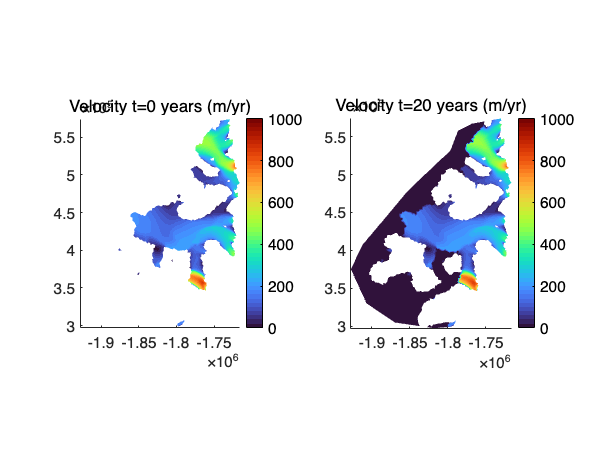

md.results.TransientSolution(1).Vel (md.results.TransientSolution(1).Vel == 0) = nan;
md.results.TransientSolution(end).Vel (md.results.TransientSolution(end).Vel == 0) = nan;

%Plot results
plotmodel(md, 'data', md.results.TransientSolution(1).Vel,'title#1', 'Velocity t=0 years (m/yr)',...
  'data', md.results.TransientSolution(20).Vel,'title#2', 'Velocity t=20 years (m/yr)',...
  'caxis#1',([0 1000]),'caxis#2',([0 1000]));

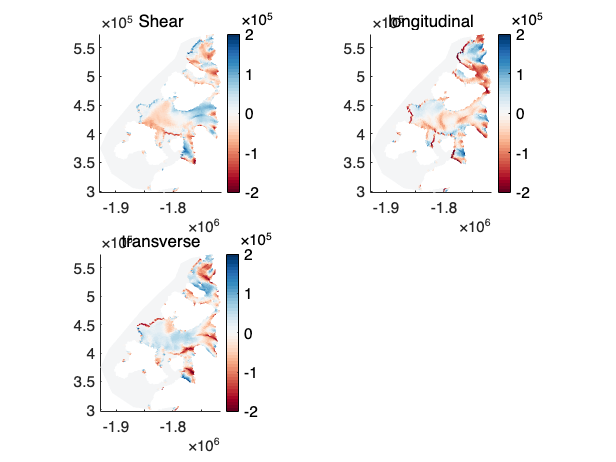

% try to produce the mechanical properties of an ice shelf from the
% transient run

% This is the stress and strain output of the first year before run
vx1 = md.results.TransientSolution(1).Vx;
vy1 = md.results.TransientSolution(1).Vy;
md = mechanicalproperties(md, vx1, vy1);
md.results.deviatoricstress_start = md.results.deviatoricstress;


% This is the stress and strain output of the end year after run
vxt = md.results.TransientSolution(end).Vx;
vyt = md.results.TransientSolution(end).Vy;
md = mechanicalproperties(md, vxt, vyt);
md.results.deviatoricstress_end = md.results.deviatoricstress;


%% plotting the Deviatoric Stresses for the last year
plotmodel(md,'data',md.results.deviatoricstress_start.xy,'title','Shear',...
'data',md.results.deviatoricstress_start.xx,'title','longitudinal',...
'data',md.results.deviatoricstress_start.yy,'title','transverse','caxis#all',[-2e5 2e5]);
colormap(brewermap(50, 'RdBu'));

## Use the Furst_buttressing function to calculate the changes in the backstress 

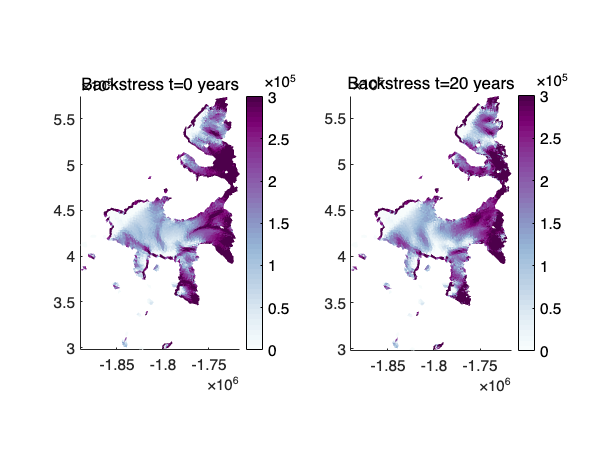

% buttressing and backstress for the initial time
vx = md.results.TransientSolution(1).Vx;
vy = md.results.TransientSolution(1).Vy;
[Kn_start, Backstress_Furst_start] = Furst_buttressing(md, vx, vy, false);  % Max buttressing

% buttressing and backstress for the end time
vx = md.results.TransientSolution(end).Vx;
vy = md.results.TransientSolution(end).Vy;
[Kn_end, Backstress_Furst_end] = Furst_buttressing(md, vx, vy, false);

% Plot them and show the difference between them
plotmodel(md,'data',Backstress_Furst_start,'title', 'Backstress t=0 years','caxis#1',[0 3e5], ...
              'data',Backstress_Furst_end,'title', 'Backstress t=20 years','caxis#2',[0 3e5])

colormap(brewermap(50,'BuPu'))

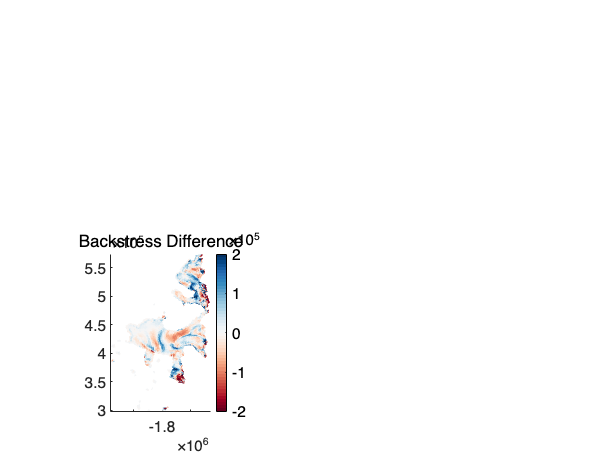

plotmodel(md,'data',(Backstress_Furst_start - Backstress_Furst_end),'title', 'Backstress Difference')
colormap(brewermap(50,'RdBu')); 
clim([-2e5 2e5])